clear
clc

# Double Taper Wing Design Calculator V1

#### By James Orendi

#### Inputs

wing_area = 132.7 ; % m^2
AR = 9.42 ; % N/A, Wing Aspect Ratio

sweep_type = 1 ;
wing_sweep = 48; % degrees

wing_dihedral = 0; % degrees

taper_ratio_t2r = 0.35 ; % N/A, Taper ratio between wingtip (numerator) and wing root (denominator)
kink_distance_ratio = 0.12 ; % N/A, Distance ratio of wing kink along wing semi-span
taper_ratio_k2r = 0.8 ; % N/A, Taper ratio between wing kink (numerator) and wing root (denominator)

#### Function Call

addpath([cd,'/Functions'])
[wing_span,c_r,c_k,c_t,wing_opp,wing_opp_2,wing_dihedral_opp,wing_kink_dihedral_opp,wing_sweep,x_wing_data,y_wing_data,wing_xlim,wing_ylim] = Planform_Calc_2taper(kink_distance_ratio,wing_area,wing_dihedral,AR,taper_ratio_t2r,taper_ratio_k2r,sweep_type,wing_sweep);
[y_mac_wing_data_root_1,y_mac_wing_data_root_2,y_mac_wing_data_kink_1,y_mac_wing_data_kink_2,y_mac_wing_data_kink_3,y_mac_wing_data_kink_4,y_mac_wing_data_tip_1,y_mac_wing_data_tip_2,x_mac_wing_data_1,x_mac_wing_data_2,x_mac_wing_data_3,x_mac_inner_point,y_mac_inner_point,y_mac_data_inner,x_mac_outer_point,y_mac_outer_point,x_mac_outer_point_wing,y_mac_data_outer,y_mac_wing_data_inner_1,y_mac_wing_data_inner_2,y_mac_wing_data_outer_1,y_mac_wing_data_outer_2,mac_total,mac_graph_data_y,wing_graph_AC,quarter_chord_x,quarter_chord_y] = Planform_MAC_2taper(wing_span,kink_distance_ratio,c_r,c_k,c_t,wing_opp,wing_opp_2);

### MAC Calculation Plot

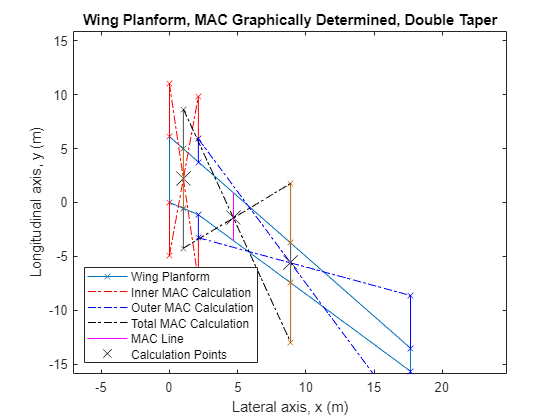

figure
plot(x_wing_data,y_wing_data,'x-')
hold on


% DISTANCE DISPLACEMENTS ITERATION 1
plot(x_mac_wing_data_1,y_mac_wing_data_root_1,'x-','Color','r')
plot(x_mac_wing_data_1,y_mac_wing_data_root_2,'x-','Color','r')

plot(x_mac_wing_data_2,y_mac_wing_data_kink_1,'x-','Color','r')
plot(x_mac_wing_data_2,y_mac_wing_data_kink_2,'x-','Color','r')
plot(x_mac_wing_data_2,y_mac_wing_data_kink_3,'x-','Color','b')
plot(x_mac_wing_data_2,y_mac_wing_data_kink_4,'x-','Color','b')

plot(x_mac_wing_data_3,y_mac_wing_data_tip_1,'x-','Color','b')
plot(x_mac_wing_data_3,y_mac_wing_data_tip_2,'x-','Color','b')

% MAC GRADIENT LINES ITERATION 1
% INNER
plot([x_mac_wing_data_1(1),x_mac_wing_data_2(1)],[y_mac_wing_data_root_1(1),y_mac_wing_data_kink_2(2)],'r-.')
plot([x_mac_wing_data_1(1),x_mac_wing_data_2(1)],[y_mac_wing_data_root_2(2),y_mac_wing_data_kink_1(1)],'r-.')
% OUTER
plot([x_mac_wing_data_2(1),x_mac_wing_data_3(1)],[y_mac_wing_data_kink_3(1),y_mac_wing_data_tip_2(2)],'b-.')
plot([x_mac_wing_data_2(1),x_mac_wing_data_3(1)],[y_mac_wing_data_kink_4(2),y_mac_wing_data_tip_1(1)],'b-.')
% MAC LOCATIONS ITERATION 1
plot(x_mac_inner_point,y_mac_inner_point,'kx','MarkerSize',15)
plot(x_mac_outer_point_wing,y_mac_outer_point,'kx','MarkerSize',15)

plot([x_mac_inner_point,x_mac_inner_point],y_mac_data_inner, '-','Color',[0.75 0.375 0])
plot([x_mac_outer_point_wing,x_mac_outer_point_wing],y_mac_data_outer, '-','Color',[0.3 0.3 0.3])

% DISTANCE DISPLANEMENTS ITERATION 2
plot([x_mac_inner_point,x_mac_inner_point],y_mac_wing_data_inner_1,'x-','Color',[0.3 0.3 0.3])
plot([x_mac_inner_point,x_mac_inner_point],y_mac_wing_data_inner_2,'x-','Color',[0.3 0.3 0.3])

plot([x_mac_outer_point_wing,x_mac_outer_point_wing],y_mac_wing_data_outer_1,'x-','Color',[0.75 0.375 0])
plot([x_mac_outer_point_wing,x_mac_outer_point_wing],y_mac_wing_data_outer_2,'x-','Color',[0.75 0.375 0])

% MAC GRADIENT LINES ITERATION 2
plot([x_mac_inner_point,x_mac_outer_point_wing],[y_mac_wing_data_inner_1(1),y_mac_wing_data_outer_2(2)],'-.','Color','k')
plot([x_mac_inner_point,x_mac_outer_point_wing],[y_mac_wing_data_inner_2(2),y_mac_wing_data_outer_1(1)],'-.','Color','k')


plot([mac_total(1),mac_total(1)],mac_graph_data_y,'-','Color',[1 0 1])
plot(mac_total(1),mac_total(2),'kx','MarkerSize',15)

xlim([wing_xlim(1),wing_xlim(2)]) % Graphical Display View limits, x axis
ylim([-wing_ylim,wing_ylim]) % Graphical Display View limits, y axis
title("Wing Planform, MAC Graphically Determined, Double Taper")
legend("Wing Planform","","","","","","","","","Inner MAC Calculation","","Outer MAC Calculation","","","","","","","","","","Total MAC Calculation","","MAC Line","Calculation Points","Location","southwest")
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")

### AC Location Plot

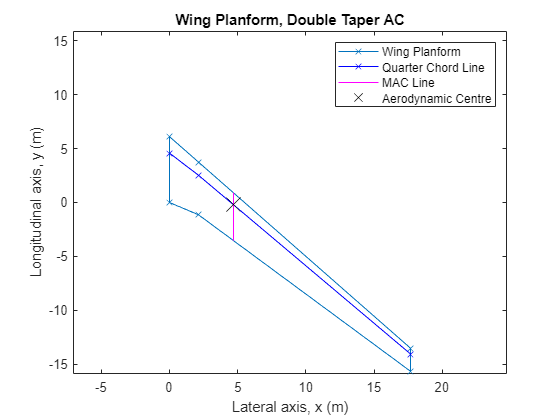

figure
plot(x_wing_data,y_wing_data,'x-')
hold on

plot(quarter_chord_x,quarter_chord_y,'x-', 'Color','b')
plot([mac_total(1),mac_total(1)],mac_graph_data_y,'-','Color',[1 0 1])
plot(wing_graph_AC(1),wing_graph_AC(2),'kx','MarkerSize',15)

xlim([wing_xlim(1),wing_xlim(2)]) % Graphical Display View limits, x axis
ylim([-wing_ylim,wing_ylim]) % Graphical Display View limits, y axis
title("Wing Planform, Double Taper AC")
legend("Wing Planform","Quarter Chord Line","MAC Line","Aerodynamic Centre")
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")

### Full Wing Planform Plot

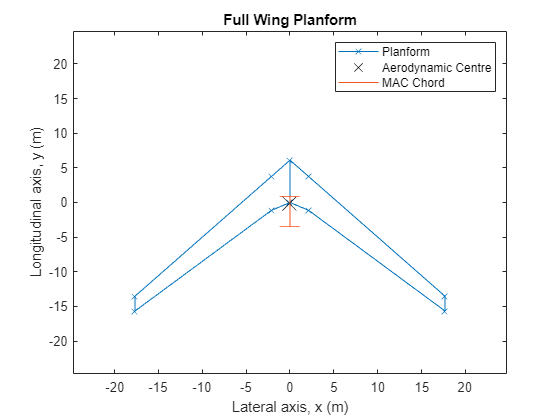

figure
plot(x_wing_data,y_wing_data,'x-',"Color",[0 0.4470 0.7410])
hold on
plot(0,wing_graph_AC(2),'x', 'color','k','MarkerSize',15)
plot(-x_wing_data,y_wing_data,'x-',"Color",[0 0.4470 0.7410])
plot([0 0],mac_graph_data_y,'_-','Color',[0.9500 0.3250 0.0980],'MarkerSize',15)
title("Full Wing Planform")
legend("Planform","Aerodynamic Centre","","MAC Chord")
xlim([-wing_xlim(2),wing_xlim(2)]) % Graphical Display View limits, x axis
ylim([-wing_xlim(2),wing_xlim(2)]) % Graphical Display View limits, y axis
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")
hold off